# Basic Image Enhancement and Analysis Techniques

This example shows how to enhance an image as a preprocessing step before analysis. The image used in this examlpe belonges to MathWorks image processing toolbox. 

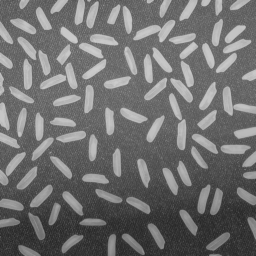

**rice.png**

The example addresses morphological operation applied on image, . 

## Clear the workspace

clear variables;    % Remove variables from the workspace
clc;                % Delete messages from the command window

## First Step: Removing background

### Displaying the image

The image is a grayscale image. This means that each pixel ranges from 0 to 255. That's why $I$is $256\times 256$of class uint8.

cImagePath = 'Images\rice.png'; % The image path
I = imread(cImagePath);         % Load image
% imshow(I);                    % Uncommit this to display the image
% imInfo = imfinfo(cImagePath)

### Background approximation

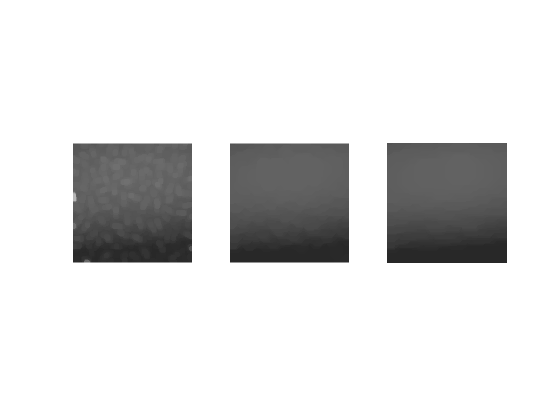

structElem = cell(1, 3);
background = cell(1, 3);
nSize = [6 15 30];
for i = 1:size(nSize, 2)
    structElem{i} = strel('disk',nSize(i)); 
    % structElem{i} = strel('rectangle',[nSize(i) nSize(i)]);
    % structElem{i} = strel('octagon', nSize(i));
    % structElem{i} = strel('diamond', nSize(i));
    background{i} = imopen(I, structElem{i});
    % figure;
    subplot(1, 3, i);
    title(sprintf('Background %d', i));
    imshow(background{i});
    % subplot(2, 3, i + 3);
    % title(sprintf('Structure element disk %d', nSize(i)));
    % imshow(structElem{i}.Neighborhood);
end

% figure
% surf(double(background(1:8:end,1:8:end))),zlim([0 255]);
% set(gca,'ydir','reverse');

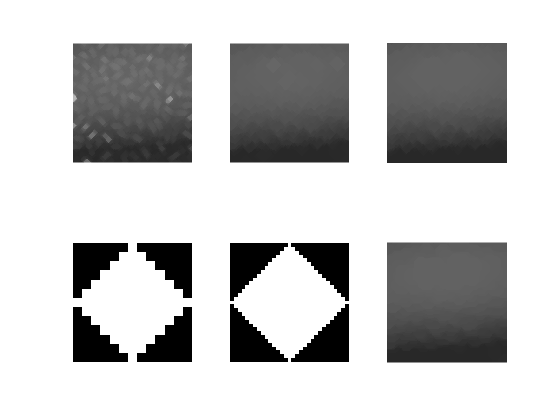

structElem = strel('disk',15);
background = imopen(I, structElem);
imshow(background);

% imshow(I);